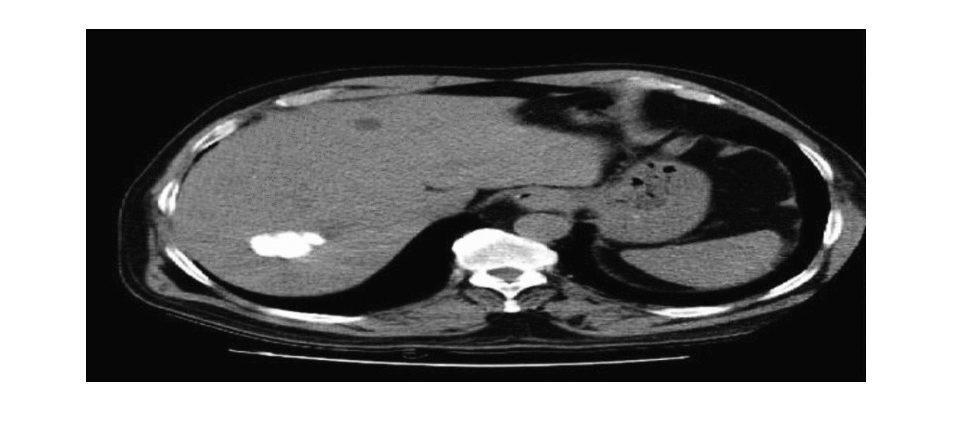


rgb = imread('E:\matlab_code\original.jpg');
I = rgb2gray(rgb);
imshow(I)

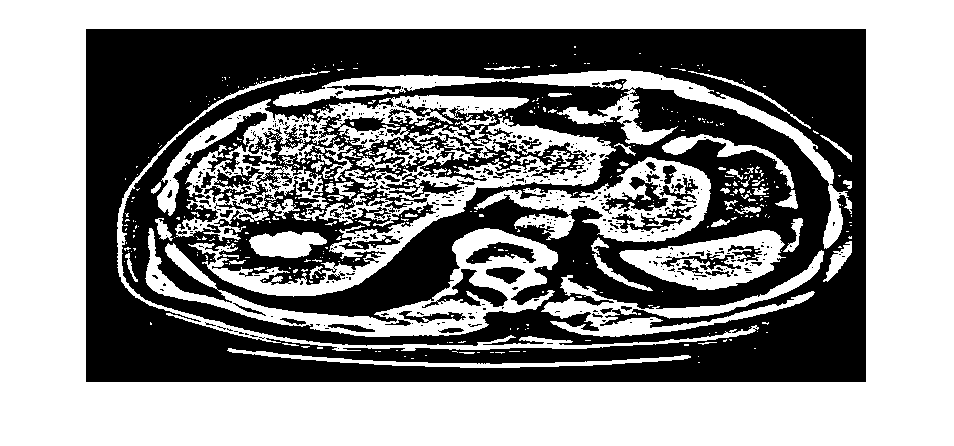

niblack1(I,26,0.34);

function [result,thresh]=niblack1(img,b,k)

% Niblack threshold
% T(i,j) = m(i,j) + k * std(i,j)
% b x b window, k is a parameter to determine the effect of the std.
% A good value for k is -0.2.

[my,mx]=size(img);
thresh=zeros(my,mx);
result=zeros(my,mx);

for x=(b/2+1):(mx-b/2-1)
    for y=(b/2+1):(my-b/2-1)
        
        box=img( (y-(b/2)):(y+(b/2)), (x-(b/2)):(x+(b/2)) );
        thresh(y,x)=mean(mean(double(box))) + k*std(std(double(box)));
        if img(y,x)>thresh(y,x)
            result(y,x)=1;
        end
        
    end
end
imshow(result)
end